## RRT

% parking lot costmap generation for real world parking lot
parking_spot = 4;
road_file_path = 'ParkingLotGeneration/ParkingLines/polylines9.shp';
parking_points_file_path = 'ParkingLotGeneration/ParkingSpots/points6.shp';
car_width  = 0.000005;
car_length = 0.00002;
road_f = shaperead(road_file_path);
points_f = shaperead(parking_points_file_path);
info = shapeinfo(road_file_path);
boundary_bounds = info.BoundingBox;
min_col = boundary_bounds(1, 1);
min_row = boundary_bounds(1, 2);
max_col = boundary_bounds(2, 1);
max_row = boundary_bounds(2, 2);
cost_map = parking.costmap(road_f, max_row, min_row, max_col, min_col);

startPos = int64([0,0,0]); %x,y,theta (radians)
goalPose = [53,38,pi];
iterations = 2000;
dis = 10;
tolerance = 3;

% Matlab parking valet inputs
ws = load('input_variables_from_matlab_parking_example.mat');
startPos = ws.currentPose;
costmap = ws.combinedMap;
minTurning = 4;
routePlan = ws.routePlan;
goalPoses = num2cell(routePlan.EndPose, 2);
for i = 1: length(goalPoses)
    goalPoses{i}(3) = degtorad(goalPoses{i}(3));
end
iterations = 600;

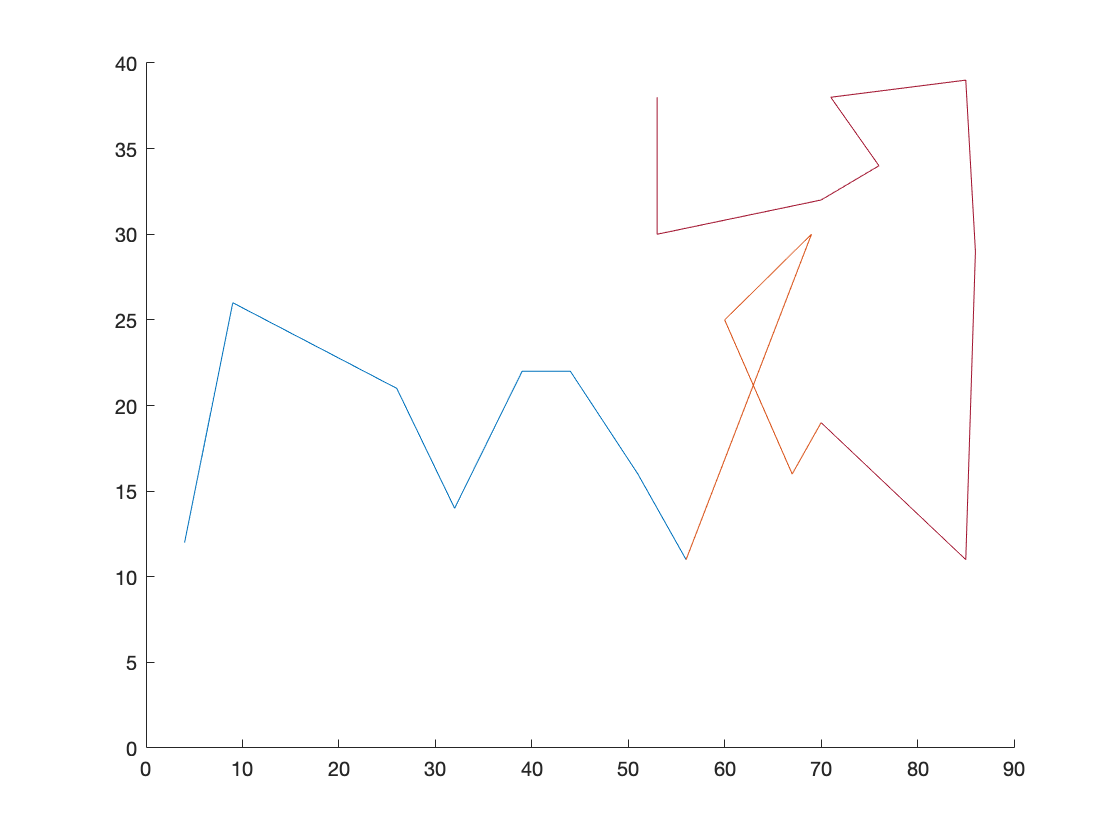

     4    12     0

    9.0000   26.0000    1.2278

   26.0000   21.0000    5.9971

   32.0000   14.0000    5.4210

   39.0000   22.0000    0.8520

    44    22     0

   51.0000   16.0000    5.5746

    56    11     0



    56    11     0

   69.0000   30.0000    0.9707

   60.0000   25.0000    3.6487

   67.0000   16.0000    5.3734

   70.0000   19.0000    1.5708



   70.0000   19.0000    1.5708

   85.0000   11.0000    5.7932

   86.0000   29.0000    1.5153

   85.0000   39.0000    1.6705

   71.0000   38.0000    3.2129

   76.0000   34.0000    5.6084

   70.0000   32.0000    1.5708



   70.0000   32.0000    1.5708

   53.0000   30.0000    3.2587

   53.0000   38.0000    3.1416



figure
hold on
for i = 1:length(goalPoses)
    tree = rrt(costmap, iterations, startPos, goalPoses{i}, minTurning, dis, tolerance);
    [path, Tree]= run(tree);
    for j = 1: length(path)
        disp(path{j});
    end
    [X1, Y1, ~] = convert_cell_vector_to_double_vectors(path);
    plot(X1, Y1);
    startPos = goalPoses{i};
end


% tree = rrt(costmap, iterations, startPos, goalPose, minTurning, dis, tolerance);
% [path, Tree]= run(tree);
% for j = 1: length(path)
%     disp(path{j});
% end

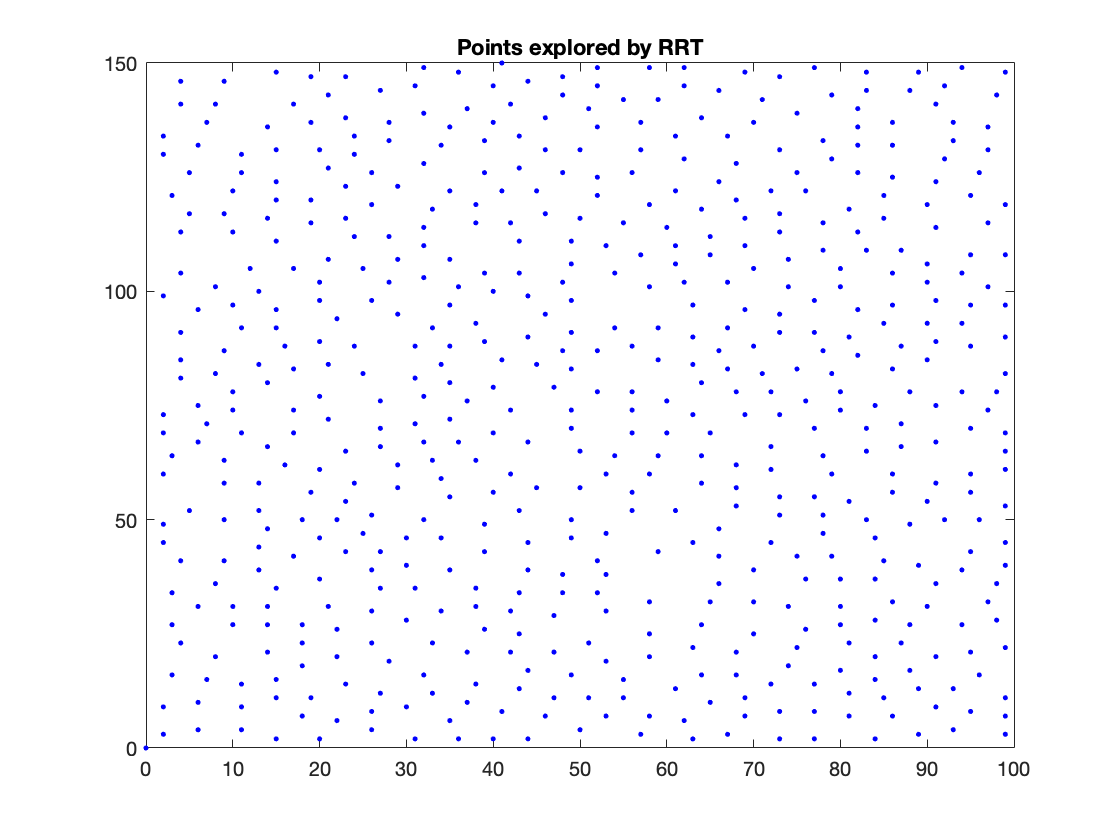

[X, Y, Theta] = convert_cell_vector_to_double_vectors(tree.nodes);
figure
plot(X, Y, 'b.')
title('Points explored by RRT')

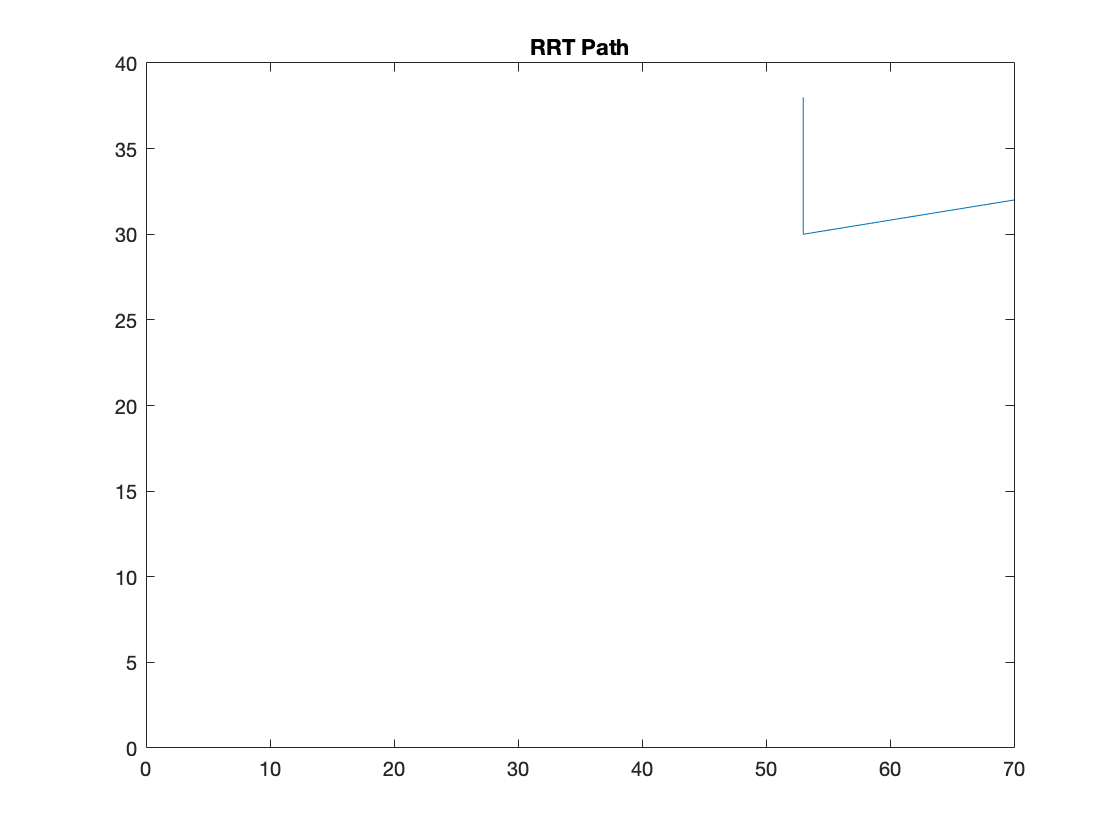

[X1, Y1, Theta1] = convert_cell_vector_to_double_vectors(path);
figure
plot(X1, Y1)
title('RRT Path')

%% Processing for plotting, should we just change the data structure itself
% this way?? Open Question...

function [X, Y, Theta] = convert_cell_vector_to_double_vectors(data)
    size = length(data);
    X = zeros(size);
    Y = zeros(size);
    Theta = zeros(size);
    for i = 1:size
        n = data{i};
        X(i) = n(1);
        Y(i) = n(2);
        Theta(i) = n(3);
    end
end
%%reference link:
%https://github.com/Mayankm96/Motion-Planning-GUI/blob/master/GUI/RRTree/RRT.m
